## 这个例子测试双积分系统的欧拉法积分误差

模型： $\ddot{x} = u$

零初始条件

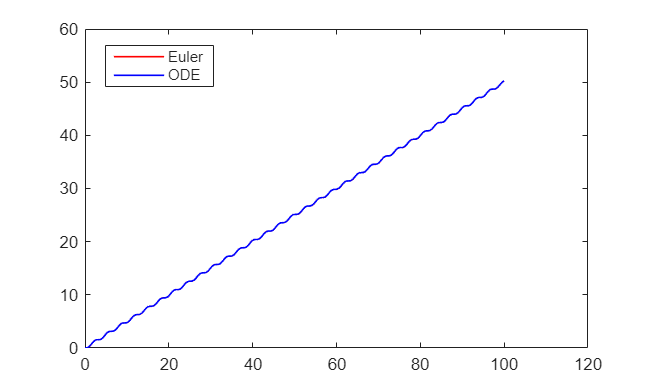

span = [0, 10];
Ts = 1e-3; 
K = round((span(2) - span(1)) / Ts);
x = zeros(K + 1, 2);
x(1,:) = [0, 0];
t = zeros(1, K +1);
t(1) = span(1);
u = @(t) sin(2*t);
for i = 1 : K
    t(i + 1) = t(i) + Ts;
    ddx = u(t(i));
    x(i + 1, 1) = x(i, 1) +  x(i, 2) * Ts;
    x(i + 1, 2) = x(i, 2) + ddx * Ts;
end

[tt, xx] = ode45(@(t, x) [x(2); u(t)], span, [0;0]);

plot(t, x(:,1), 'r', tt, xx(:,1), 'b', 'LineWidth',1);
legend({'Euler', 'ODE'});

legend(["Euler", "ODE"], "Position", [0.1676 0.7802 0.1550, 0.1013])